# Read in the RX data

txname='tx_x1.dat';
dat=read_usrp_data_file(txname);

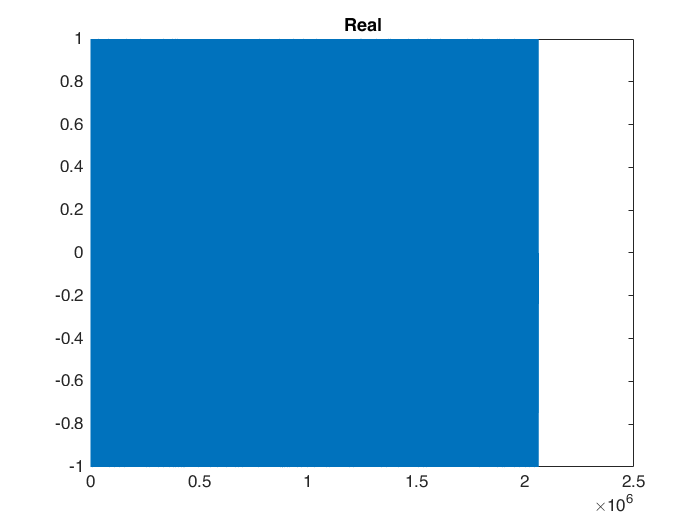

rxname='baby_its_cold_outside.dat';
read=sign(read_usrp_data_file(rxname));

% Plot the real and imaginery part
figure
plot(real(read))
title('Real')

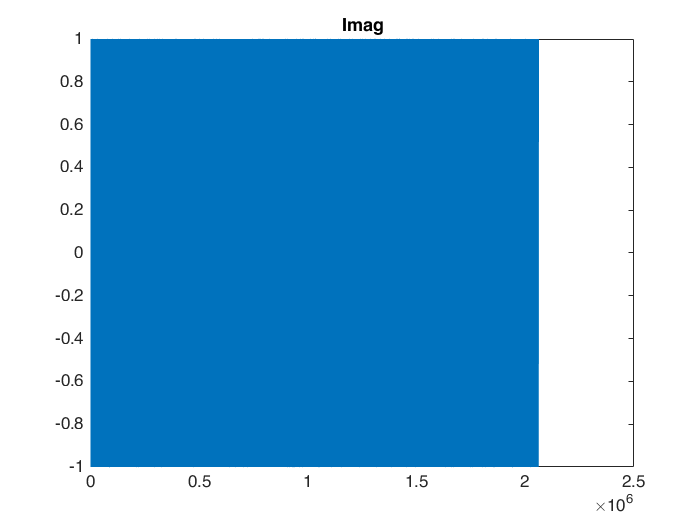

figure
plot(imag(read))
title('Imag')

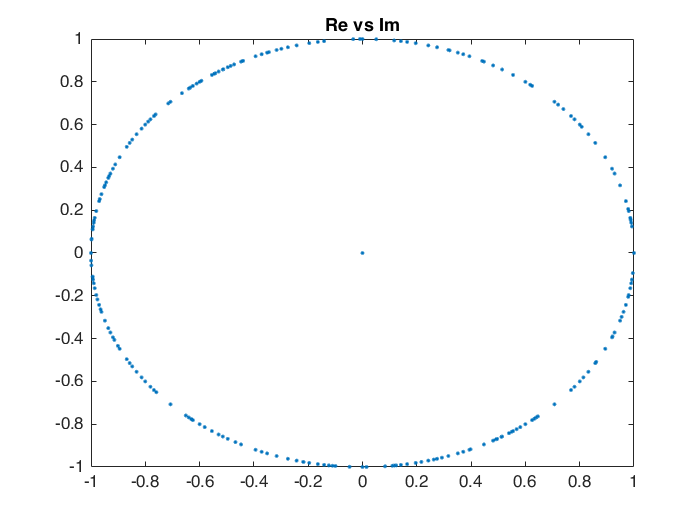


% Plot real vs imaginary
figure
plot(real(read),imag(read),'.')
title('Re vs Im')

## Autocorrelation of the real part

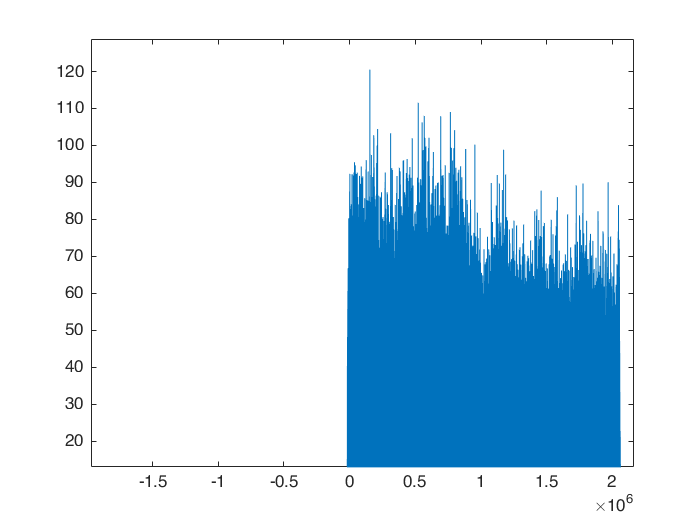

[r, lags]=xcorr(real(read),real(dat));
plot(lags,abs(r))

% xlim([-10^5 10^5])
% ylim([-.2 .2])

## Autocorrelation of the imaginery part

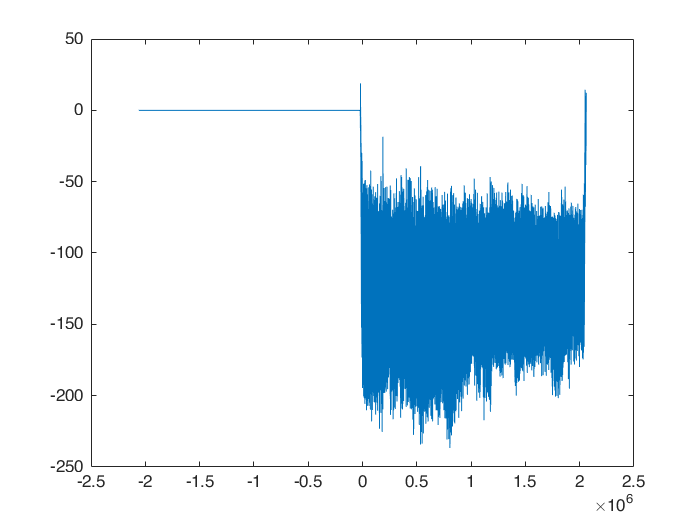

[r, lags]=xcorr(imag(read),imag(dat));
plot(lags,r)

% xlim([-10^5 10^5])
% ylim([-.2 .2])

## Error Rate Calculation

read_ds=read(805798:end);
read_ds=downsample(read_ds,20);
error=-1*sign(real(read_ds(1:length(dat))))-real(dat);
err_num=length(find(error~=0));
err_rate=err_num/(length(dat));
err_rate

err_rate = 0.8008

## Attempt to adjust for phase shifting

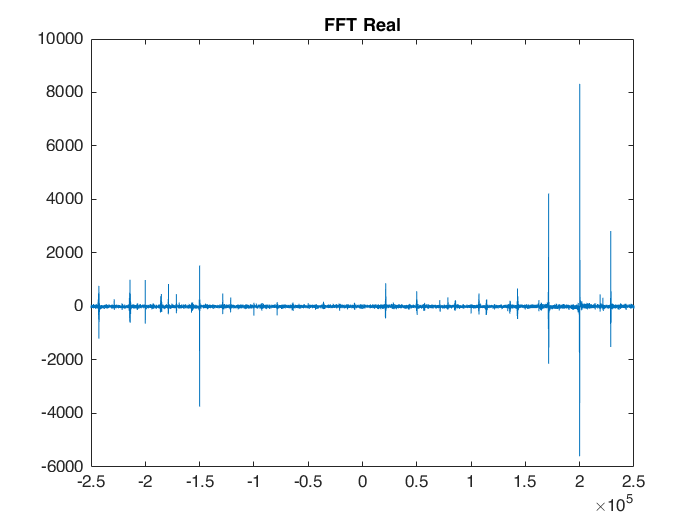

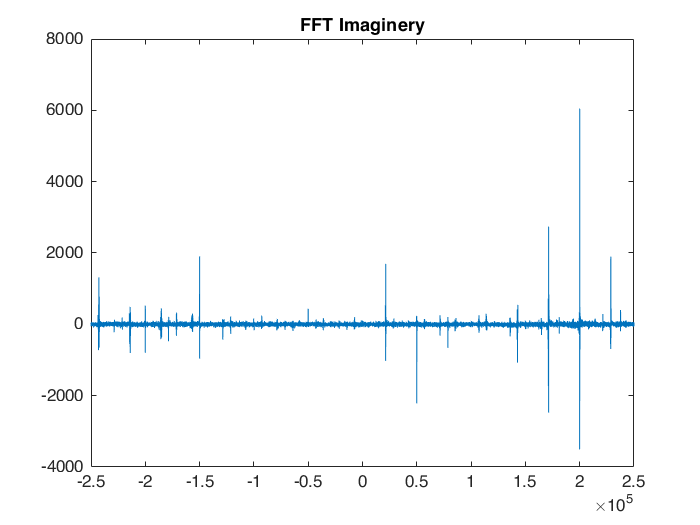

y_norm=read_ds./rms(read_ds);
y_norm_2=y_norm.^2;
plot_FT(y_norm_2, 500000);


% 2f = 200000
% 2phi = arctan(-1422497.7246/-642656);

phi=atan(6046/8322);
f=200008/2;

k=1:length(dat);
offset=exp(-1j*(f*(k-1)*1/500000+phi));
read_ds=read(153580:153580+length(dat)-1);
% read_ds=downsample(read_ds,20);
read_offset=times(read_ds,offset');

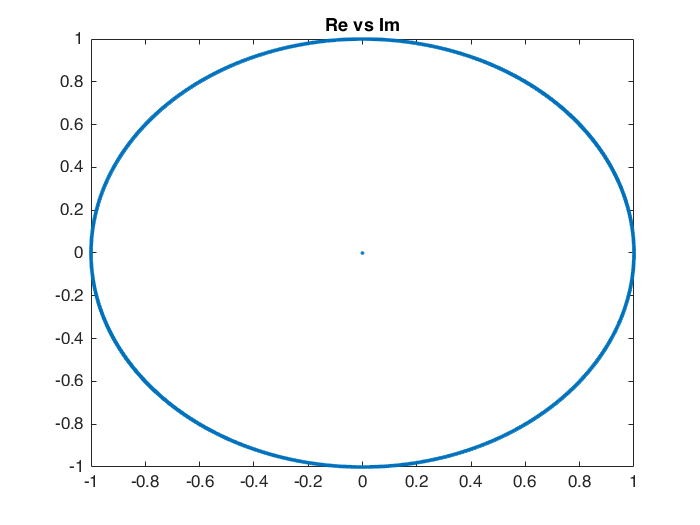


% Plot real vs imaginary
figure
plot(real(read_offset),imag(read_offset),'.')
title('Re vs Im')